# Exercise 4

## Graph Search

### About This Exercise

When traveling across country, having a map is essential, but how do you decide on what route to take? Some routes might be longer but have higher speed limits. Any given route might have new construction or an accident blocking traffic. To select a route on a graph, you can use one of numerous graph search algorithms that will explore the paths from the start towards the goal given the weights of the edges (that might represent the distance between or the time it would take to travel) as well as other factors.

The goal of this exercise is to create a function that takes in a graph, starting node, and ending node and returns a route using Dijskra's algorithm, a simple graph seach algorithm, and A*, which adds an additional heuristic to better direct the search.

**By the end of this exercise, you'll be able to: **

- **Use Dijskra's algorithm to identify the shortest route for your robot given the roadmap.**

### Dijkstra's Algorithm

You will develop a function that implements Dijkstra's Algorithm, which is a relatively intuitive and straightforward graph search algorithm. The idea is to explore outwards from the starting node, and to choose the next node from which to explore based on a cost, which is the sum of all the weights of the edges on the path to each explored node. That means that if there are two nodes connected to the first, we will first explore the paths heading out from the node that is easier to get to. We may even find the goal without needing to explore the other node if the cost to arrive at the goal is lower than the cost of traveling to that node.

However, it may be the case that the less costly paths actually lead us away from the goal, and thus we might be wasting time exploring those. In that case, we can add a heuristic to the cost that changes how we choose which nodes we should next explore. A simple example would be to add the distance the node is from the goal to the cost, so that we are less likely to explore nodes that push us away from the goal. This more generalized graph search is called A* ("A star"), which is widely used in robotics. Note that the heuristic must fit some conditions that we don't discuss in this course, but the distance heuristic works well.

[► Complete the graphSearch function](matlab:open('./graphSearch.mlx')), which implements both algorithms described above. 

Again, we need to set get a graph given obstacles.

lim = 4;
p1x = [-2  -1 1 2 1 -1];
p1y = [0 1 1 0 -1 -1]-1;
p2x = [-2 0 .5 -1];
p2y = [3 3 2 2];

obstacle(1).px = p1x;
obstacle(1).py = p1y;
obstacle(2).px = p2x;
obstacle(2).py = p2y;

We'll use the visibilityRoadmap developed, though you can also try the one based off of the cell decomposition. If your function works properly changing the sliders should plot the shortest path from S to D. 

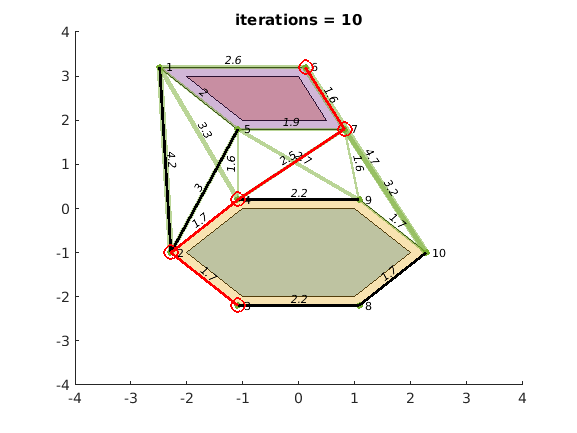

[G,A,nodes_xy,polyvec,polyvecbuf] = visibilityRoadmap(obstacle);
S = 3;
D = 6;
[path,iterations,hist] = graphSearch(A, S, D);

plotGraph(polyvec, polyvecbuf, lim, G, nodes_xy, path, iterations, hist);

What happens to the iterations of the algorithm as you choose to either include the heurisitic H or not as an argument into graphSearch. Here H is a matrix of the distances between all of the nodes. The result should be the same but note the difference in iterations from above and how much of the graph has been searched.

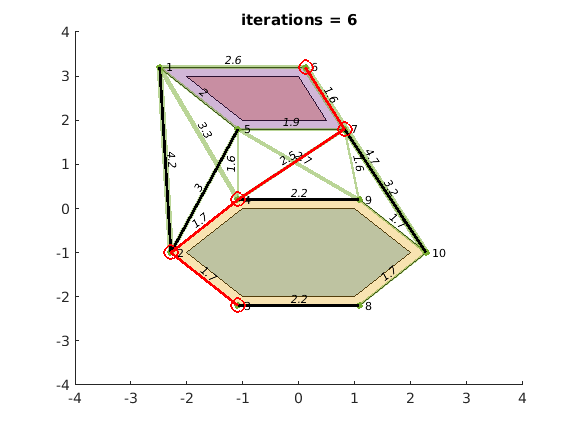

H = zeros(size(A));
for i = 1:size(nodes_xy,2)-1
    for j = i+1:size(nodes_xy,2)
        H(i,j) = norm(nodes_xy(:,i)'-nodes_xy(:,j)');
    end
end
H = H+H'; % This is a matrix of the Euclidean distances from each node to all other nodes
[path,iterations,hist] = graphSearch(A, S, D, H);


plotGraph(polyvec, polyvecbuf, lim, G, nodes_xy, path, iterations, hist);

If you're curious to see what each iteration of the search looks like as an animation, use this code after running one of the sections above.

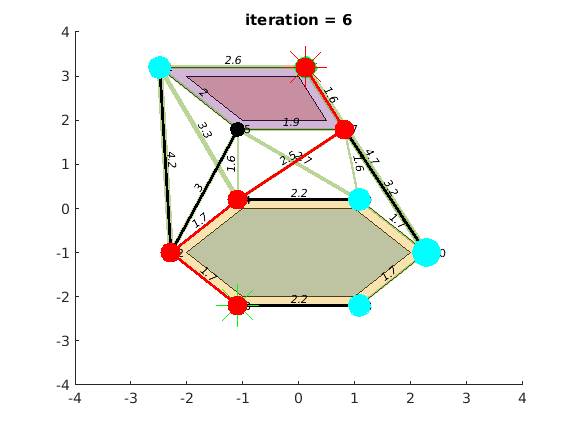

animateSearch(polyvec, polyvecbuf, lim, G, nodes_xy, hist, S, D, path)

### Finished!

Now you have a function that will return the shortest path between two nodes on a given graph. You now have all the tools you need to implement these methods for motion planning with the robot in the Simulator. Next, for the project of this course, you will use this with your previous followWaypoints function to drive the robot from one point to the next.

% This code creates the plots for this exercise. 
% PLEASE DO NOT MODIFY THIS CODE. 

function plotGraph(polyvec, polyvecbuf, lim, G, nodes_xy, path, iterations,hist)
figure;
plot(polyvec)
hold on
plot(polyvecbuf)
axis([-lim lim -lim lim])
LWidths = 5*G.Edges.Weight/max(G.Edges.Weight);
plot(G,'XData',nodes_xy(1,:),'YData',nodes_xy(2,:),'EdgeLabel',str2num(num2str(G.Edges.Weight,'%.1f')),'LineWidth',LWidths)


idx = find(hist(end).prev ~= 0);

for j = 1:length(idx)
    plot(nodes_xy(1,[idx(j) hist(end).prev(idx(j))]),nodes_xy(2,[idx(j) hist(end).prev(idx(j))]),'k-','LineWidth',2);
end
plot(nodes_xy(1,path),nodes_xy(2,path),'r-o','Markersize',10,'LineWidth',2)
title(['iterations = ' num2str(iterations)])
end

function animateSearch(polyvec, polyvecbuf, lim, G, nodes_xy, hist, S, D, path)
figure
plot(polyvec)
hold on
plot(polyvecbuf)
axis([-lim lim -lim lim])
LWidths = 5*G.Edges.Weight/max(G.Edges.Weight);
plot(G,'XData',nodes_xy(1,:),'YData',nodes_xy(2,:),'EdgeLabel',str2num(num2str(G.Edges.Weight,'%.1f')),'LineWidth',LWidths)
colors = 'kgbc';

for i = 1:length(hist(1).prev)
    hs(i) = plot([-10 -10],[-10 -10],'k-','LineWidth',2);
end
for i = 4:-1:1
    h(i) = scatter([],[]);
    h(i).MarkerEdgeColor = colors(i);
    h(i).MarkerFaceColor = colors(i);
end
plot(nodes_xy(1,S),nodes_xy(2,S),'*g','MarkerSize',30)
plot(nodes_xy(1,D),nodes_xy(2,D),'*r','MarkerSize',30)


for i = 1:length(hist)
    title(['iteration = ' num2str(i)])
    idx = find(hist(i).done == 1);
    h(1).XData = nodes_xy(1,idx);
    h(1).YData = nodes_xy(2,idx);
    h(1).SizeData = 20*hist(i).cost(idx)+10;
    h(2).XData = [];
    h(2).YData = [];
    h(2).SizeData = [];
    drawnow
    pause(0.25)
    h(2).XData = nodes_xy(1,hist(i).C);
    h(2).YData = nodes_xy(2,hist(i).C);
    h(2).SizeData = 30*hist(i).cost(hist(i).C)+10;
    h(3).XData = [];
    h(3).YData = [];
    h(3).SizeData = [];
    drawnow
    pause(0.25)
    idx = find(hist(i).tempcost<inf & hist(i).done == 0);
    h(3).XData = nodes_xy(1,idx);
    h(3).YData = nodes_xy(2,idx);
    h(3).SizeData = 30*hist(i).tempcost(idx)+10;
    drawnow
    pause(0.25)
    h(3).XData = [];
    h(3).YData = [];
    h(3).SizeData = [];
    idx = find(hist(i).cost<inf & hist(i).done == 0);
    h(4).XData = nodes_xy(1,idx);
    h(4).YData = nodes_xy(2,idx);
    h(4).SizeData = 30*hist(i).costh(idx)+10;
    idx = find(hist(i).prev ~= 0);
    
    for j = 1:length(idx)
        hs(idx(j)).XData = nodes_xy(1,[idx(j) hist(i).prev(idx(j))]);
        hs(idx(j)).YData = nodes_xy(2,[idx(j) hist(i).prev(idx(j))]);
    end
    
    drawnow
    pause(0.25)
end
plot(nodes_xy(1,path),nodes_xy(2,path),'r.-','Markersize',50,'LineWidth',2)
end